clc,clear,close all

syms d
syms calculationFunc(d)

digits(18);

%-----------Information-----------

sigmaS= 5:0.05:9.5;
sigmaF=1.5;
g=9.81;
v=21.69;

mainFunctions=sym([1,size(sigmaS,2)]);

for i=1:size(sigmaS,2)
    mainFunctions(1,i)= vpa((((3*g*d*(sigmaS(1,i)-sigmaF))/sigmaF).^(0.5))-v,14);
end

mainFunctions


%-------- Part A - Secant Method ---------

preResult=sym([1,size(sigmaS,2)]);
MiddleResult=sym([1,size(sigmaS,2)]);
result1=sym([1,size(sigmaS,2)]);

repeats= 30;

disp("Wait a while....")

Wait a while....



for j=1:size(sigmaS,2)
 
    calculationFunc(d)=mainFunctions(1,j);
    preResult= 0;
    MiddleResult= 15;

    for i=1:repeats
        up=((preResult*calculationFunc(MiddleResult))-(MiddleResult*calculationFunc(preResult)));
        down=(calculationFunc(MiddleResult)-calculationFunc(preResult));
        if down == 0
            break
        end
        result1(1,j)= up/down;
        preResult=MiddleResult;
        MiddleResult=result1(1,j);
    end
end

result1

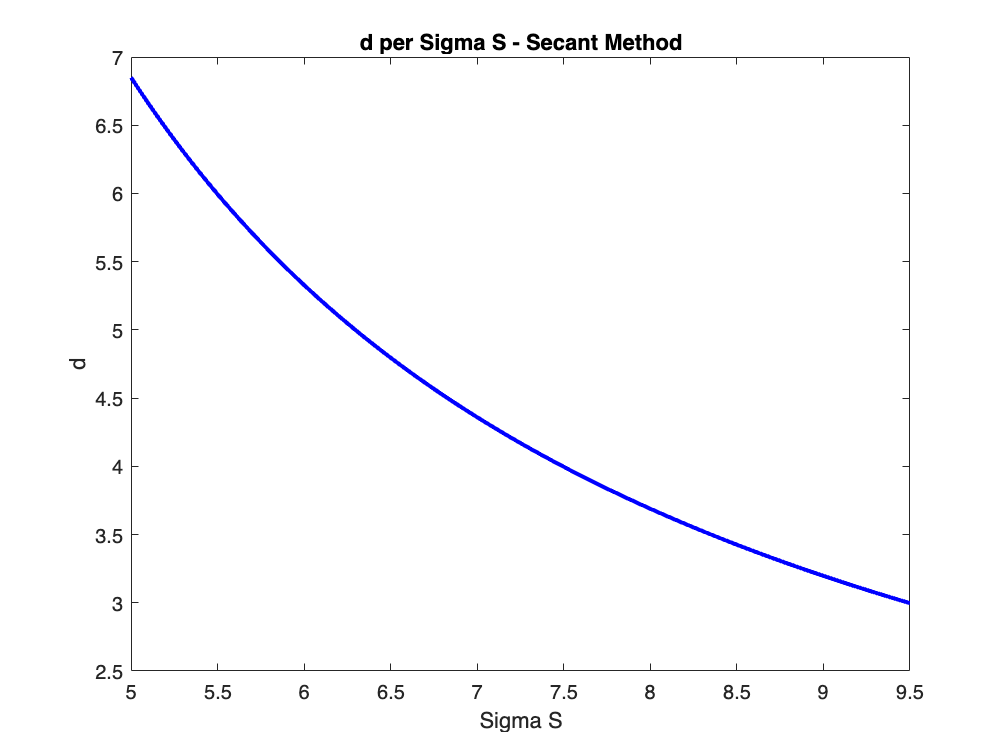


plot(sigmaS,result1,'b','LineWidth',2);
title('d per Sigma S - Secant Method');
xlabel('Sigma S');
ylabel('d');


%----------- Part B - Bisection Method ------------

result2=sym([1,size(sigmaS,2)]);
repeats=40;
disp("Wait a while....");

Wait a while....



for j=1:size(sigmaS,2)

    calculationFunc(d)=mainFunctions(1,j);
    firstGuess=0;
    secondGuess=100;

    for i=1:repeats
        result2(1,j) = (firstGuess+secondGuess)/2;
        if 0 > calculationFunc(firstGuess)*calculationFunc(result2(1,j))
            secondGuess=result2(1,j);
        else
            firstGuess=result2(1,j);
        end
    end
end

result2= vpa(result2)

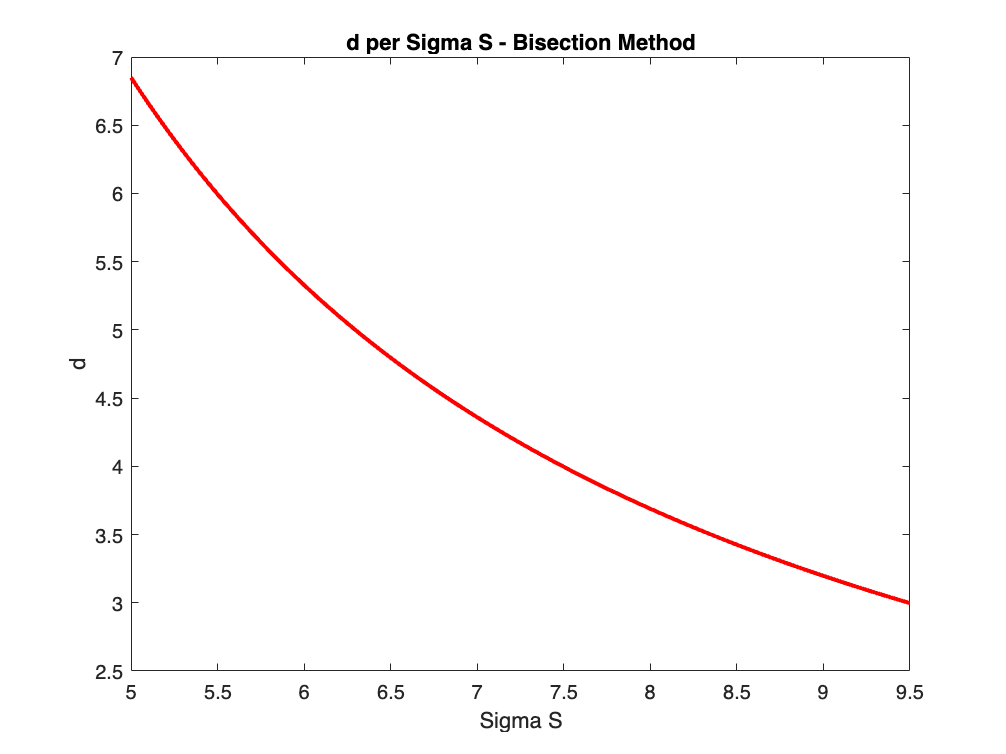


plot(sigmaS,result2,'r','LineWidth',2);
title('d per Sigma S - Bisection Method');
xlabel('Sigma S');
ylabel('d');


%-------Part C - Rearranging and Errors -----

result3 = sym([1,size(sigmaS,2)]);

for i=1:size(sigmaS,2)
    result3(1,i)= (sigmaF*(v^2))/(3*g*(sigmaS(1,i)-sigmaF));
end

result3 = vpa(result3)

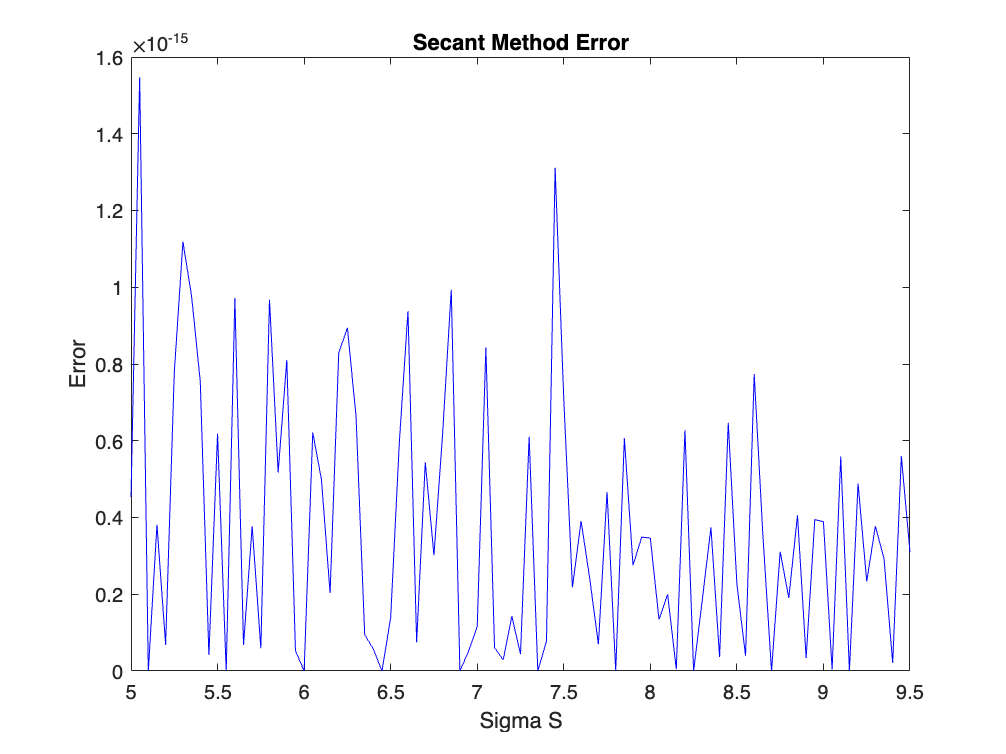


error1= abs(result3-result1);
error2= abs(result3-result2);

plot(sigmaS,error1,'b');
title('Secant Method Error');
xlabel('Sigma S');
ylabel('Error');

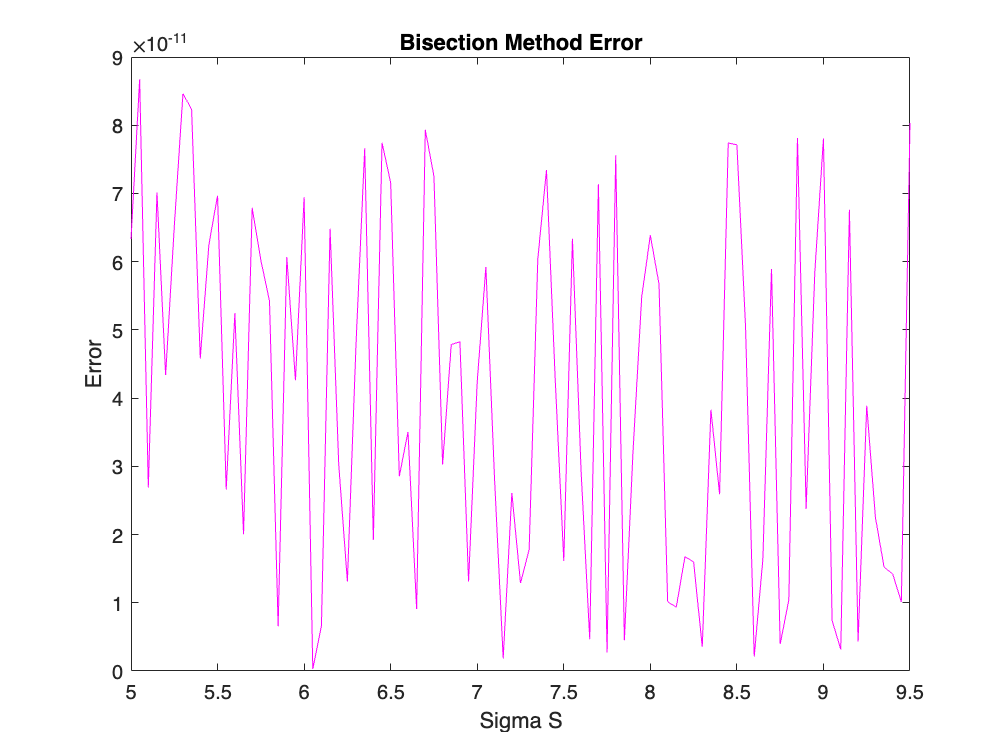


plot(sigmaS,error2,'m');
title('Bisection Method Error');
xlabel('Sigma S');
ylabel('Error');